**초기화**

clear all;
close all;

**서브 디렉토리 포함 학습 데이터 입력**

inputsize_row = 405;
inputsize_col = 720;
channel = 3;

inputsize = [inputsize_row, inputsize_col];
imagesize = [inputsize_row, inputsize_col, channel];
imds = imageDatastore('/Users/sowon/Documents/MATLAB/training',  'IncludeSubfolders', true, 'LabelSource', 'foldernames');
imgs = readall(imds);

test_imds = imageDatastore('/Users/sowon/Documents/MATLAB/test',  'IncludeSubfolders', true, 'LabelSource', 'foldernames');
test_imgs = readall(test_imds);

**데이터 확인**

% training data
imds.countEachLabel;
no_sample = imds.countEachLabel.Count(1)*length(imds.countEachLabel.Label);
res_imgs = zeros(inputsize_row, inputsize_col, channel, no_sample);

for i=1 : no_sample
    res_imgs(:, :, :, i) = imresize(imgs{i}, inputsize);
end

%test data
testsize_row = 720;
testtsize_col = 1440;
test_imds.countEachLabel;
no_testsample = test_imds.countEachLabel.Count(1)*length(test_imds.countEachLabel.Label);
res_testimgs = zeros(inputsize_row, inputsize_col, channel, no_testsample);

for i=1 : no_testsample
    res_testimgs(:, :, :, i) = imresize(test_imgs{i}, inputsize);
end

**훈련용 데이터 생성**

XTrain = res_imgs;
YTrain = categorical(imds.Labels);
no_Validation = no_sample*0.2;
idx = randperm(size(XTrain, 4), no_Validation);
XValidation = XTrain(:, :, :, idx);
XTrain(:, :, :, idx) = [];
YValidation = YTrain(idx);
YTrain(idx)= [];


**테스트용 데이터 생성**

XTest = res_testimgs;
YTest = categorical(test_imds.Labels);

**데이터 증대 - 회전, 평행 이동, 무작위 반사**

imageAugmentor = imageDataAugmenter('RandRotation', [-20, 20], 'RandXTranslation', [-3 3], 'RandYTranslation', [-3 3], 'RandXReflection', true, 'RandYReflection', true);
augimdsTrain = augmentedImageDatastore(imagesize, XTrain, YTrain, 'DataAugmentation', imageAugmentor);
augimdsValidation = augmentedImageDatastore(imagesize, XValidation, YValidation, 'DataAugmentation', imageAugmentor);

**신경망 구성**

layers = [
    imageInputLayer([inputsize_row inputsize_col 3],"Name","data")
    convolution2dLayer([11 11],96,"Name","conv1","BiasLearnRateFactor",2,"Stride",[4 4])
    reluLayer("Name","relu1")
    crossChannelNormalizationLayer(5,"Name","norm1","K",1)
    maxPooling2dLayer([3 3],"Name","pool1","Stride",[2 2])
    groupedConvolution2dLayer([5 5],128,2,"Name","conv2","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","relu2")
    crossChannelNormalizationLayer(5,"Name","norm2","K",1)
    maxPooling2dLayer([3 3],"Name","pool2","Stride",[2 2])
    convolution2dLayer([3 3],384,"Name","conv3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","relu3")
    groupedConvolution2dLayer([3 3],192,2,"Name","conv4","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","relu4")
    groupedConvolution2dLayer([3 3],128,2,"Name","conv5","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","relu5")
    maxPooling2dLayer([3 3],"Name","pool5","Stride",[2 2])
    fullyConnectedLayer(4096,"Name","fc6","BiasLearnRateFactor",2)
    reluLayer("Name","relu6")
    dropoutLayer(0.5,"Name","drop6")
    fullyConnectedLayer(4096,"Name","fc7","BiasLearnRateFactor",2)
    reluLayer("Name","relu7")
    dropoutLayer(0.5,"Name","drop7")
    fullyConnectedLayer(6,"Name","fc")
    softmaxLayer("Name","prob")
    classificationLayer("Name","classoutput")];

**구성된 신경망 확인**

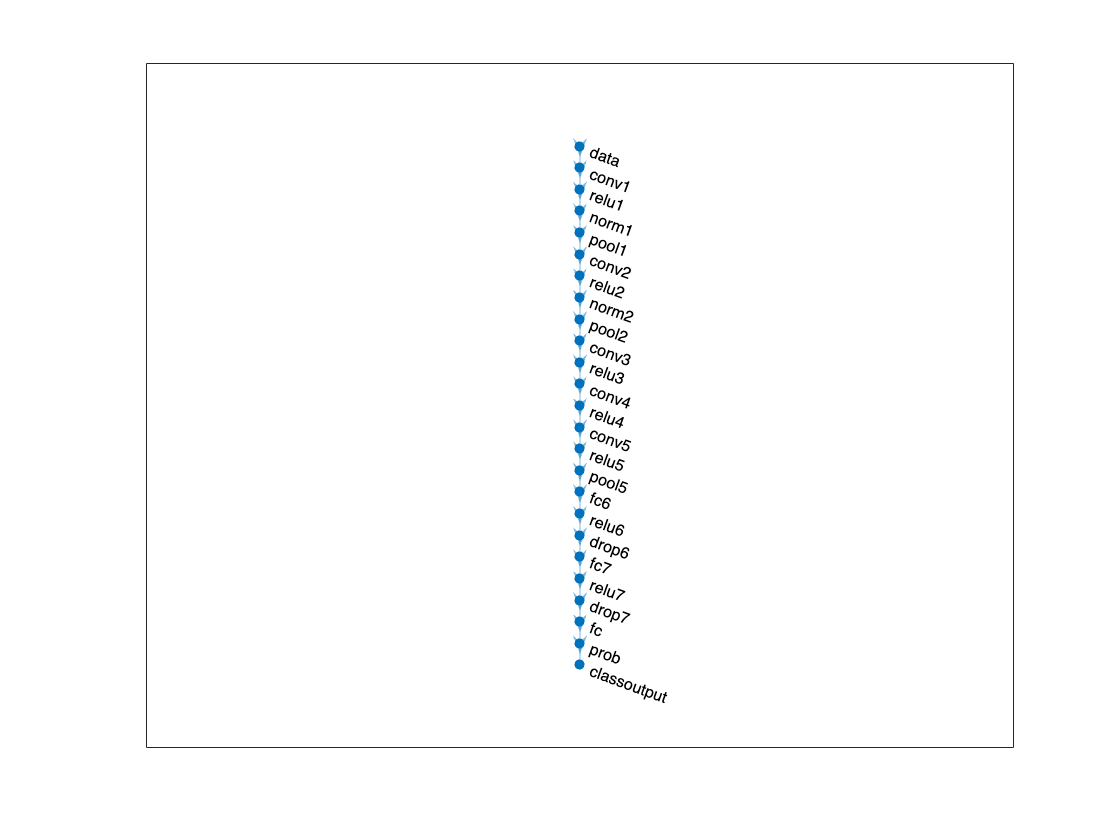

plot(layerGraph(layers));

**신경망 학습을 위한 옵션 설정**

options = trainingOptions('sgdm', ...
    'MiniBatchSize' , 10, ...
    'MaxEpochs', 100, ...
    'Shuffle','every-epoch', ...
    'InitialLearnRate', 1e-4, ...
     'ValidationData',{XValidation YValidation}, ...
    'ValidationFrequency', 3, ...
    'Verbose',false, ...
    'Plots','training-progress');

신경망 훈련

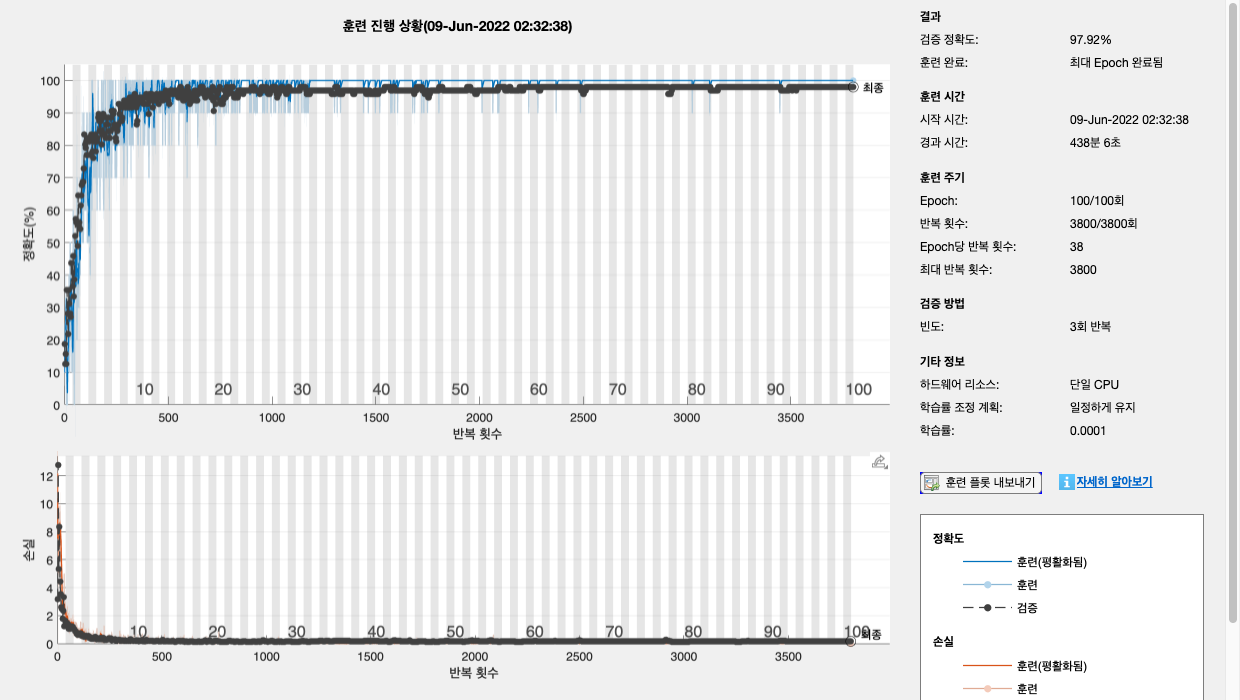

convnet =   SeriesNetwork - 속성 있음:

         Layers: [25×1 nnet.cnn.layer.Layer]
     InputNames: {'data'}
    OutputNames: {'classoutput'}


trainInfo = 다음 필드를 포함한 struct :
               TrainingLoss: [7.4988 12.1213 2.7175 9.3415 6.6681 9.7490 4.8910 8.3191 6.7831 9.0347 9.3895 9.8421 5.9326 9.4080 6.1256 6.6816 4.5936 6.0995 3.8632 5.4852 2.4458 4.0625 4.7371 3.0897 3.6746 2.8541 2.5087 2.2312 3.6195 2.0160 3.0307 … ]
           TrainingAccuracy: [20 10 30 20 30 20 40 0 10 10 10 10 0 0 30 30 30 20 20 20 30 40 10 30 10 20 50 50 30 40 40 20 30 30 20 10 10 30 10 30 40 60 30 30 50 30 0 40 40 50 50 50 40 50 10 80 40 50 30 20 30 70 40 50 30 30 40 50 50 40 70 40 60 30 50 … ]
             ValidationLoss: [3.1847 NaN 12.7487 NaN NaN 5.3291 NaN NaN 8.3632 NaN NaN 4.4203 NaN NaN 3.5562 NaN NaN 2.6207 NaN NaN 2.4997 NaN NaN 1.7665 NaN NaN 2.3525 NaN NaN 3.3249 NaN NaN 1.2582 NaN NaN 1.6404 NaN NaN 1.5133 NaN NaN 1.5086 NaN … ]
         ValidationAccuracy: [18.7500 NaN 12.5000 NaN NaN 15.6250 NaN NaN 12.5000 NaN NaN 35.4167 NaN NaN 28.1250 NaN NaN 21.8750 NaN NaN 35.4167 NaN NaN 31.2500 NaN NaN 28.1250 NaN NaN 27.0833 NaN NaN 43.7500

[convnet, trainInfo] = trainNetwork(XTrain, YTrain, layers, options)

save convnet_vgg19.mat convnet;
save vgg19_info.mat trainInfo;
analyzeNetwork(convnet);

**Validation 데이터 평가**

load convnet_vgg19.mat
YPred = classify(convnet, XValidation);
accuracy = sum(YPred == YValidation)/numel(YValidation)

accuracy = 1

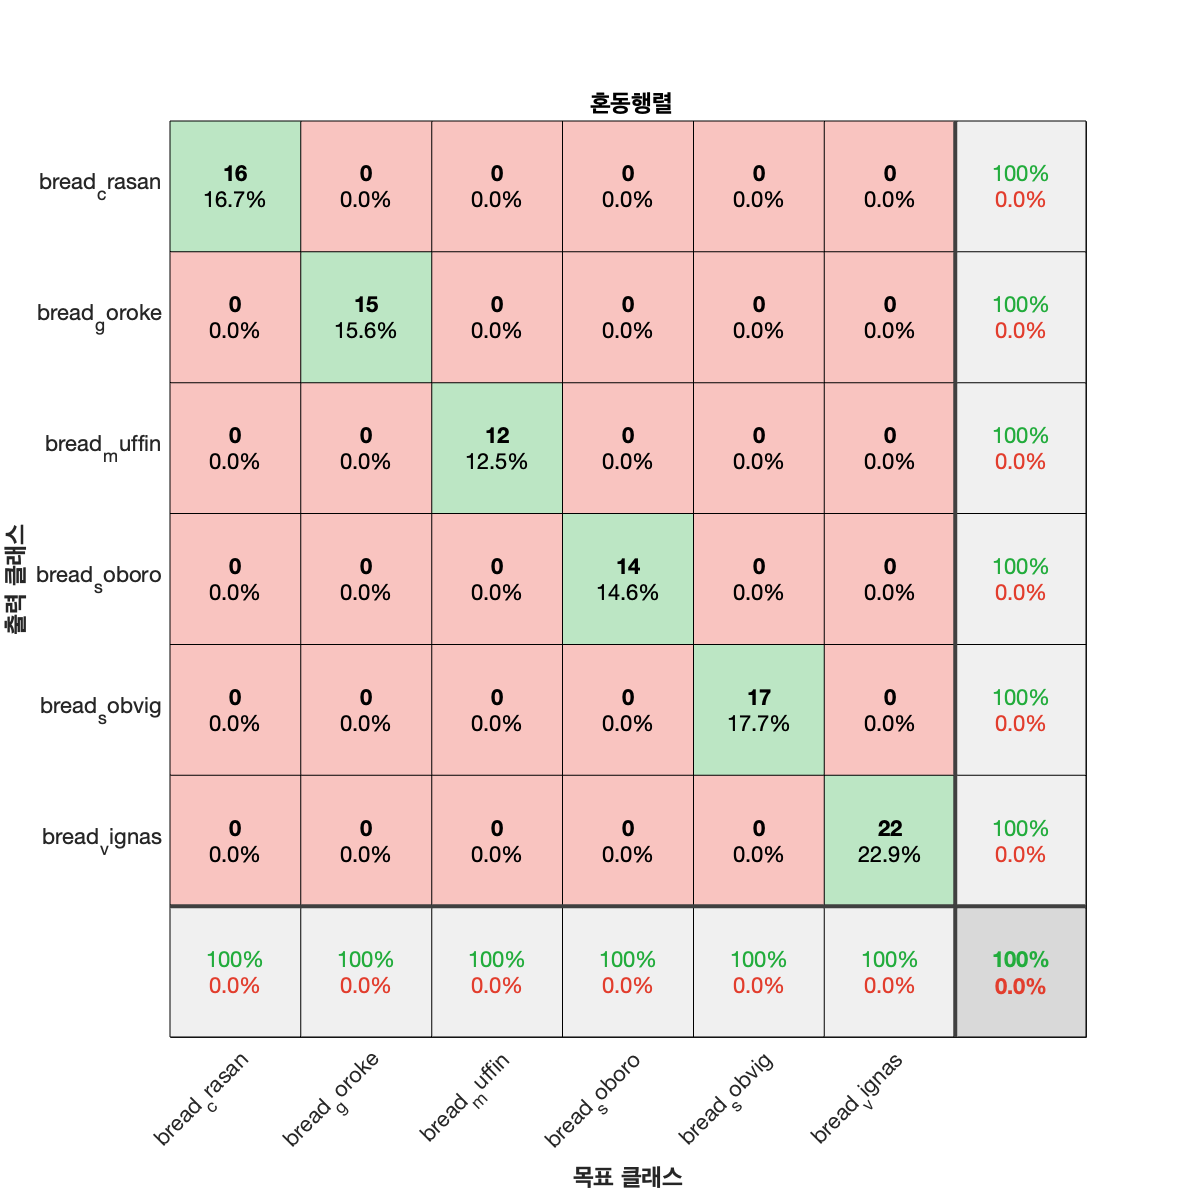

plotconfusion(YValidation, YPred)

**테스트 데이터 평가**

YPred_Test = classify(convnet, XTest);
accuracy = sum(YPred_Test == YTest)/numel(YTest)

accuracy = 0.8000

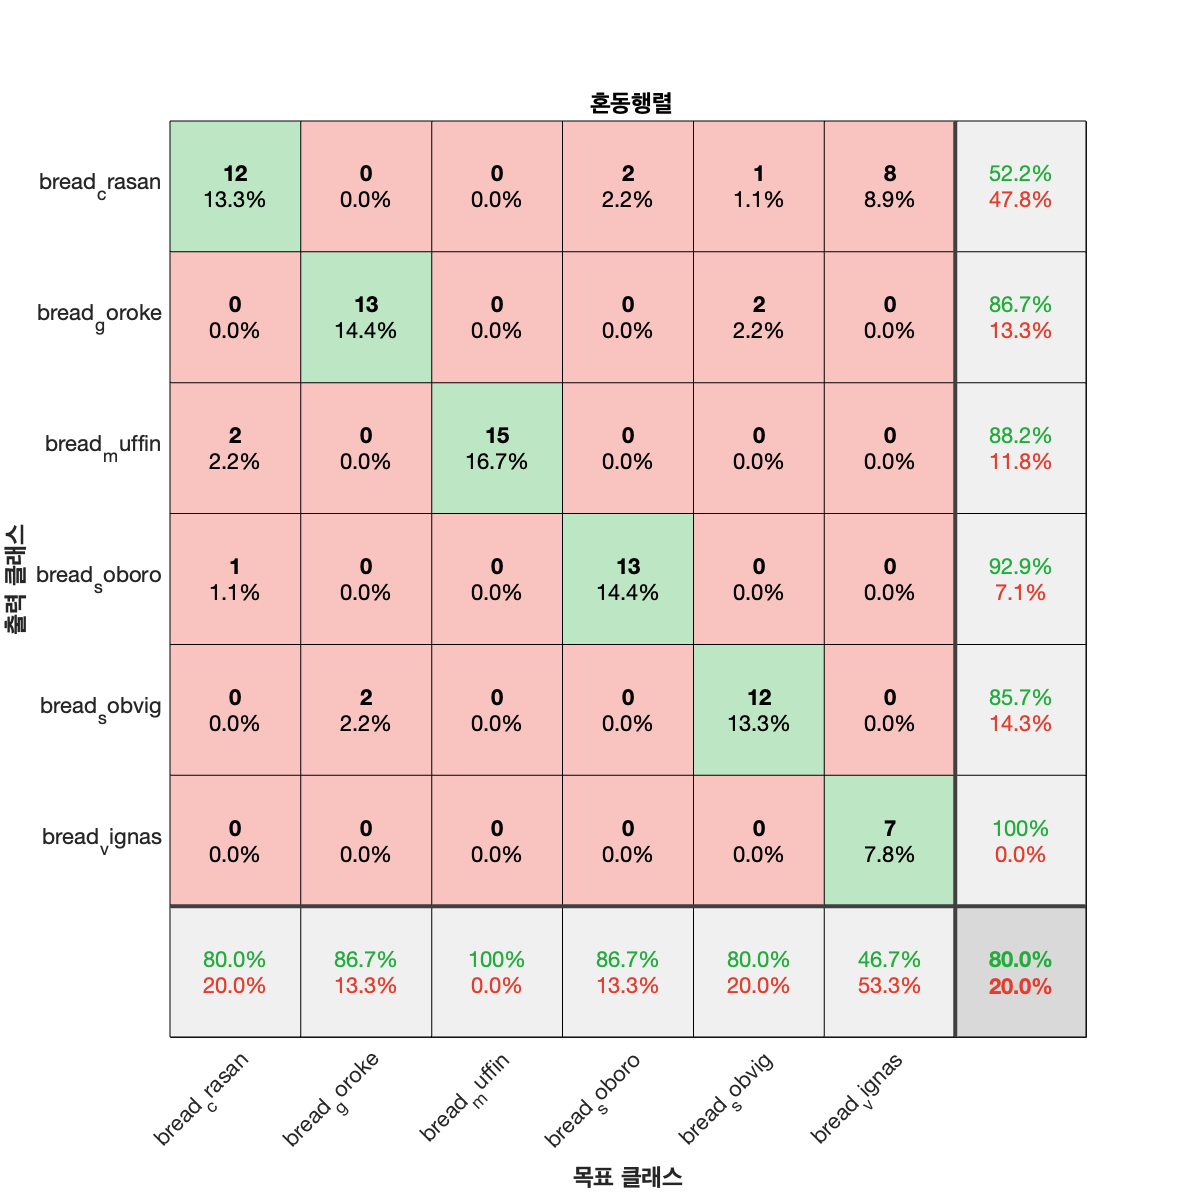

plotconfusion(YTest, YPred_Test)

**precision, recall**

cm = confusionmat(YTest, YPred_Test);
cmt = cm'

cmt =     12     0     0     2     1     8
     0    13     0     0     2     0
     2     0    15     0     0     0
     1     0     0    13     0     0
     0     2     0     0    12     0
     0     0     0     0     0     7



diagonal = diag(cmt)

diagonal =     12
    13
    15
    13
    12
     7


sum_of_rows = sum(cmt, 2)

sum_of_rows =     23
    15
    17
    14
    14
     7


precision = diagonal ./ sum_of_rows

precision =     0.5217
    0.8667
    0.8824
    0.9286
    0.8571
    1.0000


overall_precision = mean(precision)

overall_precision = 0.8427

sum_of_columns = sum(cmt, 1)

sum_of_columns =     15    15    15    15    15    15


recall = diagonal ./ sum_of_columns'

recall =     0.8000
    0.8667
    1.0000
    0.8667
    0.8000
    0.4667


overall_recall = mean(recall)

overall_recall = 0.8000